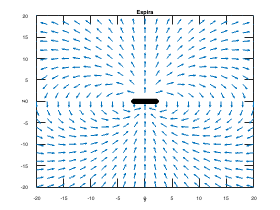

clc
clear

% Datos iniciales

%Primeramente se estipula concretamente el radio de la espira.
radio = 5; 
%Procedemos a calcular la  permeabilidad magnética del vacío.
mu0 = 4*pi*(10.^-7); 
% corriente que cruza la espira
corriente = 1; 



%A continuación se estipulan los parámetros
%para la función “linspace” (min, max, N), la cual es
%aquella que nos devuelve un vector de elementos
%equiespaciados a partir del valor inicial y final
%siguiendo el rango correspondiente.

%Número de vectores en X y Y.
n = 21; 
%Aquí se debe de estipular valores máximos  y
%mínimos en X
%De x= -20 a x= 20

Zmin = -20;
Zmax = 20;

%Aquí se debe de estipular valores máximos y
%mínimos en Y

%De y= -20 a y= 20
Ymin = -20;
Ymax = 20;


%Generamos la función linspace en X y Y con los
%respectivos parámetros que creamos anteriormente.

y = linspace(Zmin, Zmax, n); % vector de posiciones en eje Y
z = linspace(Ymin, Ymax, n); % vector de posiciones en eje Z


%Generamos el Grid con ayuda de la función
%meshgrid estableciendo como parámetros x y y. 
%Donde básicamente la función meshgrid nos devuelve 
%las coordenadas de cuadrícula de dos dimensiones en base  a 
%los vectores estipulados.

[y, z] = meshgrid(y, z); % meshgrid cuadrado



% Establecemos valores de las posibles r
r = sqrt((y.^2) + (z.^2));

% Coeficiente constante entre By y Bz
coef = (mu0*corriente*radio.^2)./(4*r.^3);

% Cálculo del campo magnético en eje Y
By = coef .* ((3.*y.*z)./(r.^2));
%Cálculo del campo magnético en el eje Z
Bz = coef .* (((3.* z.^2)./(r.^2)) - 1);

% Magnitud de los vectores de campo magnético.
mag_vec = sqrt((By.^2) + (Bz.^2));

%Normalización del vector Y
By_norm = By./mag_vec;
%Normalización del vector Z
Bz_norm = Bz./mag_vec;

% Graficación del campo magnético mediante la estipulación de la
% argumentación de la cuadrícula MeshGrid en Y y Z, además de los vectores
% de campo magnético normalizados mediante la división del respectivo
% componente y su magnitud. 
quiver(y,z,By_norm,Bz_norm,'AutoScaleFactor',0.5);
hold on 


%Se estipula el eje Y graficamente, donde irá de manera horizontal en sí.
xlabel('y');
%Se estipula el eje Z graficamente, donde irá de manera vertical en sí.
ylabel('z');
%Se establece el título en sí.
title('Espira');


%Los límites de X y Y serán concretamente limitados a un mínimo de 20 en el
%eje de las abscisas negativamente y postiviamente dicho coeficinete; por
%el otro lado, en el eje de la ordenada, los límites asmismo serán estipulados 
% con un mínimo de -20 y máximo de 20 en sí.
xlim([-20, 20]);
ylim([-20, 20]);


%Con la función Rectangle se establecerá el radio, donde primeramente se
%estipula la posición insertando: "-radio/2 -0.5 radio 1" l asimismo acordando la cuvatura,
%que en si será uno porque es un círculo. Por último se concerta el color en sí del aro, donde
%en este caso es negro. 
rectangle('Position', [-radio/2 -0.5 radio 1], 'Curvature',1, 'Facecolor','black');